# specDataOverview

A ideia deste arquivo de teste é apresentar a organização da principal propriedade do **appAnalise** – `specData` – acessível no app por `app.specData`.

Ela é uma instância da classe `model.SpecData`, que faz parte do projeto **appAnalise**, e tem como superclasse `model.SpecDataBase`, pertencente ao projeto **SupportPackages**.

A seguir, é mostrado um trecho da superclasse `model.SpecDataBase`.

Note que se trata de uma classe do tipo *handle*, o que significa que mudanças em suas propriedades são feitas **por referência** – ou seja, não são criadas cópias; qualquer modificação afeta diretamente o mesmo objeto na memória.

As principais informações armazenadas em `specData` são:

(a) **MetaData** – Estrutura com campos como `FreqStart`, `FreqStop`, `DataPoints`, `Resolution`, `TraceMode`, `Detector`, entre outros.

(b) **Data** – Lista com pelo menos três elementos:

- Data{1}: Vetor linha `1 x nSweeps` contendo os *timestamps*;

- Data{2}: Matriz `DataPoints x nSweeps` com os níveis das varreduras em dBm, dBμV ou dBµV/m;

- Data{3}: Matriz `DataPoints x 3` contendo informações de **MinHold**, **Average** e **MaxHold** de toda a monitoração.

Quando a monitoração é um *Drive-Test* conduzido pelo **appColeta**, do tipo *Level+Azimuth*, são adicionados dois elementos extras:

- Data{4}: Matriz `DataPoints x nSweeps` com os azimutes de cada ponto de medição em graus (de 0 a 360º);

- Data{5}: Matriz `DataPoints x nSweeps` com notas de qualidade dos azimutes (de 0 a 100%).

(c) **GPS** – Estrutura que resume a informação de localização da monitoração. Para *Drive-Tests*, esse campo contém apenas o ponto médio da rota.

(d) **RelatedFiles** – Tabela com informações detalhadas por arquivo, incluindo dados brutos de GPS, o que permite o georreferenciamento das varreduras, caso a coleta tenha sido realizada por meio de um *Drive-Test*.

A seguir, é mostrado um trecho da classe model.SpecData.

Note que uma instância de model.SpecData, além de herdar propriedades e métodos de model.SpecDataBase, tem as suas próprias propriedades e métodos. Dentre as propriedades, a mais importante é:

(e) **UserData** – Instância da classe model.User, que faz parte do projeto **appAnalise**, e armazena informações não originadas no arquivo bruto de medição, mas pelo appAnalise ou pelo próprio usuário.

## Aspectos gerais

No projeto SupportPackages, na pasta "tests/resources/SpecDataBase", tem alguns arquivos de referência gerados pelo Logger (RFEye), appColeta, CelPlan e Argus (R&S). No presente teste, será lido um arquivo desse pasta que foi gerado pelo Logger.

testFolder = fullfile(fileparts(fileparts(fileparts(fileparts(which('model.SpecDataBase'))))), 'tests');

% Cria instância da classe, inicialmente vazia.
specData   = model.SpecDataBase.empty;

## Leitura do arquivo

fileName   = fullfile(testFolder, 'resources', 'SpecDataBase', 'rfeye002292_210211_T111912.bin');
specData   = read(specData, fileName, 'SingleFile');

% O arquivo gerado pelo Logger possui informação espectral de quatro faixas
% de frequências.
specData

specData = 1×4 SpecDataBase array with properties:
    Receiver
    MetaData
    Data
    GPS
    RelatedFiles
    FileMap
    Enable


% Faixas de frequências:
strjoin(arrayfun(@(x) sprintf('%.3f - %.3f MHz', x.MetaData.FreqStart/1e+6, x.MetaData.FreqStop/1e+6), specData, 'UniformOutput', false), '\n')

ans =     '50.000 - 90.000 MHz
     70.000 - 110.000 MHz
     170.000 - 220.000 MHz
     470.000 - 700.000 MHz'


## Informações registradas em um dos fluxos espectrais

idx = 2;
specData(idx)

ans =   SpecDataBase with properties:

        Receiver: 'RFeye002292'
        MetaData: [1×1 struct]
            Data: {[1×245 datetime]  [1024×245 single]  [1024×3 single]}
             GPS: [1×1 struct]
    RelatedFiles: [1×10 table]
         FileMap: []
          Enable: on


% Pelas dimensões de "Data", evidencia-se que foram coletadas 245 varreduras, e que 
% cada varredura é formada por 1024 pontos.

% Na propriedade "MetaData" são registrados os principais metadados - FreqStart, 
% FreqStop, Resolution e VBM, tudo em "Hertz", além do número de pontos por
% varredura (DataPoints), o modo de traço (TraceMode), o detector, dentre outros.
specData(idx).MetaData

ans = struct with fields:
            DataType: 67
           FreqStart: 70000000
            FreqStop: 110000000
          DataPoints: 1024
          Resolution: 73828
                 VBW: -1
           Threshold: -1
           TraceMode: 'Peak'
    TraceIntegration: -1
            Detector: ''
           LevelUnit: 'dBµV/m'
             Antenna: [1×1 struct]
              Others: ''


% Sumarização da informação do GPS...
specData(idx).GPS

ans = struct with fields:
            Status: 1
             Count: 4
          Latitude: -12.9716
         Longitude: -38.4815
      Latitude_std: 4.0000e-06
     Longitude_std: 2.0000e-06
          stdRange: [50 100 100]
          Location: 'Salvador/BA'
    LocationSource: 'API'
            Edited: 0


% Arquivos relacionados ao fluxo espectral... nem sempre a relação será de
% um para um já que o appAnalise mescla fluxos que possuem os mesmos
% metadados.
specData(idx).RelatedFiles

ans = 1×10 table
                   File                      Task       ID                 Description                       BeginTime                EndTime           nSweeps    RevisitTime        GPS                           uuid                  
    __________________________________    __________    __    ______________________________________    ____________________    ____________________    _______    ___________    ____________    ________________________________________

    {'rfeye002292_210211_T111912.bin'}    {'Script'}    20    {'PRD 2021 (Faixa principal 2 de 4).'}    11-Feb-2021 11:19:12    11-Feb-2021 11:23:16      245        1.0007 

% A informação detalhada de GPS fica em coluna da tabela "RelatedFiles",
% no campo "Matrix".
specData(idx).RelatedFiles.GPS{1}

ans = struct with fields:
            Status: 1
             Count: 4
          Latitude: -12.9716
         Longitude: -38.4815
      Latitude_std: 4.0000e-06
     Longitude_std: 2.0000e-06
          stdRange: [50 100 100]
          Location: 'Salvador/BA'
    LocationSource: 'API'
            Matrix: [4×2 double]
            Edited: 0


% Latitude e Longitude, ambos organizados em coluna.
specData(idx).RelatedFiles.GPS{1}.Matrix

ans =   -12.9716  -38.4815
  -12.9716  -38.4815
  -12.9716  -38.4815
  -12.9716  -38.4815


% Um trecho do vetor linha de timestamps...
specData(idx).Data{1}(1:10)

ans = 1×10 datetime array
   11/02/2021 11:19:12   11/02/2021 11:19:13   11/02/2021 11:19:14   11/02/2021 11:19:15   11/02/2021 11:19:16   11/02/2021 11:19:17   11/02/2021 11:19:18   11/02/2021 11:19:19   11/02/2021 11:19:20   11/02/2021 11:19:21


% E um trecho da matriz de níveis...
specData(idx).Data{2}(1:10,1:10)

ans = 10×10 single matrix
   24.0000   27.5000   24.5000   31.0000   28.5000   27.0000   32.0000   26.5000   22.5000   25.5000
   30.5000   25.5000   26.5000   28.0000   27.5000   25.5000   27.0000   30.0000   12.5000   30.5000
   22.0000   21.0000   31.5000   29.0000   26.0000   22.5000   26.5000   26.5000    4.5000   36.5000
   18.5000   28.0000   34.0000   24.5000   27.0000   31.0000   30.5000   24.0000   23.0000   34.5000
   21.5000   27.0000   35.5000   24.5000   29.0000   28.0000   31.0000   22.5000   21.0000   28.5000
   28.0000   16.5000   38.0000   26.5000   16.0000   28.5000   26.0000   27.0000   21.5000   29.5000
   32.5000   15.0000   40.5000   30.5000   16.0000   30.5000   11.5000   27.5000   24.0000   28.5000
   30.0000   22.0000   38.5000   30.5000   34.0000   25.0000   20.5000   25.5000    9.5000   25.5000
   21.5000   29.5000   30.0000   27.0000   36.5000   28.5000   27.0000   21.0000   30.0000   21.5000
   21.0000   31.0000   18.0000   28.5000   33.0000   31.5000   28

## Uma simples análise: busca pelo máximo e plot

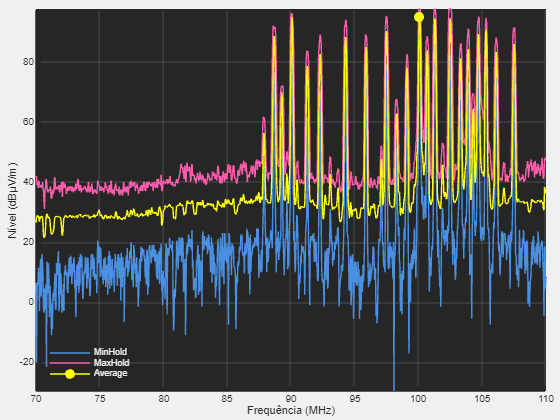

% Identificação do ponto de máximo na curva de média para 
% mostrar como um marcados no plot. Lembrando que o elemento
% Data{3} é uma matriz DataPoints x 3 contendo informações de 
% MinHold, Average e MaxHold de toda a monitoração.
[~, idxPeakMax] = max(specData(idx).Data{3}(:,2));

% Criação de figura e eixo:
f  = uifigure();
ax = uiaxes(f, 'Units', 'normalized', 'Position', [0.01,0.01,.98,.98], ...
               'YGrid', 'on', 'XGrid', 'on', 'GridColor', [.8,.8,.8],  ...
               'Color', [.15,.15,.15], 'FontSize', 10);

% Configuração do eixo:
xData = linspace(specData(idx).MetaData.FreqStart / 1e+6, ... % Hertz >> MHz
                 specData(idx).MetaData.FreqStop  / 1e+6, ...
                 specData(idx).MetaData.DataPoints);

[yDataMin, yDataMax] = bounds(specData(idx).Data{3}, "all");

set(ax, XLim = [xData(1), xData(end)], YLim = [yDataMin, yDataMax])
xlabel(ax, 'Frequência (MHz)')
ylabel(ax, ['Nível (' specData(idx).MetaData.LevelUnit ')'])
legend(ax, 'Location', 'southwest', 'Box', 'off', 'TextColor', [.94,.94,.94])
hold(ax, "on")

% Plot
plot(ax, xData, specData(idx).Data{3}(:,1), 'Color', '#4A90E2', 'DisplayName', 'MinHold');
plot(ax, xData, specData(idx).Data{3}(:,3), 'Color', '#FF5CAD', 'DisplayName', 'MaxHold');
plot(ax, xData, specData(idx).Data{3}(:,2), 'Color', '#ffff12', 'DisplayName', 'Average', 'MarkerIndices', idxPeakMax, 'Marker', 'o', 'MarkerSize', 7, 'MarkerFaceColor', '#ffff12');